# ECSE 343: Numerical Methods for Engineers- Assignment 1- part b

Due Date: 22nd Feb. 2024

Student Name: Karen Cherry Chen Lai

Student ID:    261107674

## Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

## Please submit this **.mlx** file along with the **PDF** copy of this file.

## Question 1: Cholesky Least Squares Estimation **(10 marks)**

(a) **Cholesky factorization **is an alternative to LU decompostion which can be applied on symmetric positive definite matrices. A symmetric positive definite matrix$\mathit{\mathbf{M}}$must satisfy following two conditions:

     1. The matrix $\mathit{\mathbf{M}}$must be symmetric, i.e. $\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

     2. The matrix $\mathit{\mathbf{M}}$ must be positive definite,  i.e.  ${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$ for  all  $\mathit{\mathbf{x}}\in \Re^{N\times 1}$, $\left\|\mathit{\mathbf{x}}\right\|\not= 0$.

If the above two conditons are met then the matrix $\mathit{\mathbf{M}}$ can be factored as 


$$\mathit{\mathbf{M}}={\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}$$
                 

where $U$ is a $N\times N$the lower upper matrix with real and positive diagonal enteries. The enteries of matrix $U$ are given by the following expression 


$$\textbf{U}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{i,i} - u_i(1:i-1)^Tu_i(1:i-1) }    ,& \text{if  } i =j\\
    \frac{1}{\textbf{U}_{i,i}} \left(\textbf{M}_{i,j} - u_i(1:i-1)^Tu_j(i:i-1) \right),              & \text{if  } i<j\\
0, & \text{otherwise}
\end{cases}$$


The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. Your task is to implement the Cholesky decomposition alogorithm, the use the outline of the function named *CholeskyDecomposition* provided in the appendix.

Use the cell below to test your Cholesky decompostion code by computing the Frobenius norm of  $\left.{\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}-M\right)\ldotp$

M= [2 -1 0; -1 2 -1; 0 -1 2];

U = CholeskyDecompositon(M);

Error =  norm(U'*U-M);

disp(Error);

   NaN



 b) In regression problems we often need to solve the normal equations,  ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$.  Show that the matrix $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ is symmetric positive definite, and thus can be factored using Cholesky Decomposition.

*% ANSWER*

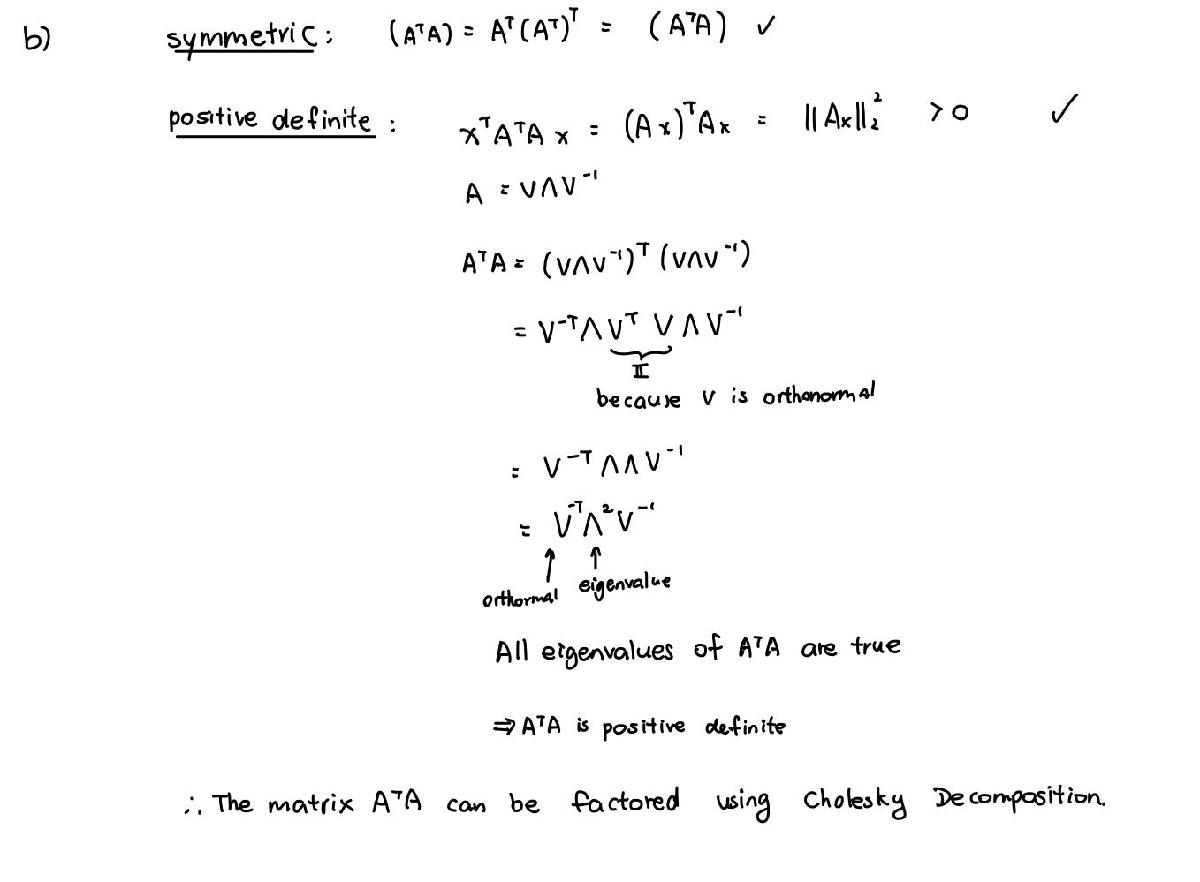

c) Using Cholesky facotrization scheme $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ can be factored as ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;={{\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} }^{\;} \mathit{\mathbf{U}}$. This transforms the normal equation into the form,


$${\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


The above equation consists of the triangular systems. The solution **x **can be obtained by  first solving ${\mathit{\mathbf{U}}}^T \;\mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ using the forward substitution, then by solving the  $\mathit{\mathbf{U}}\;\mathit{\mathbf{x}}=\mathit{\mathbf{y}}$ using backward subsitution. Implement the Cholesky solver function named *LeastSquareSolver_Cholesky  *for least squares in the function in the appendix.

Test the your Cholesky Least Square solver below.

A = rand(30,15); % random over-determined system
b = ones(30,1)

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



x = LeastSquareSolver_Cholesky(A,b);

residual = A*x-b;

Norm_residual = norm(residual);

disp(['Question 1c: The norm of the residual after solving using Cholesky based least sqaure solver is '  num2str(Norm_residual)]);

Question 1c: The norm of the residual after solving using Cholesky based least sqaure solver is NaN


## Question 2: Proofs **(10 marks)**

a) Show that the condition number of $A^TA$ is $\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$.

*% ANSWER*

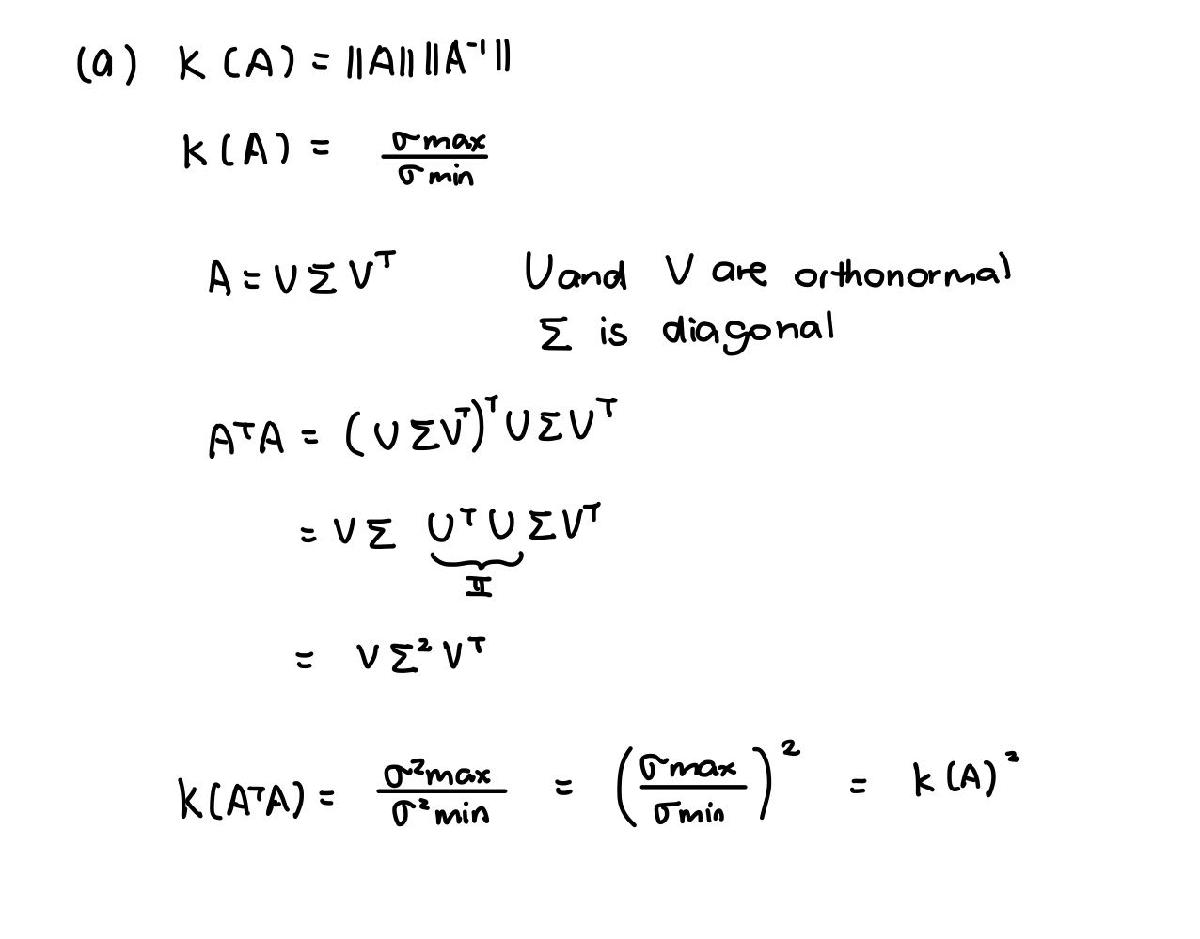

b) Given two orthonormal matrices $U$and $Q$, show that product of these matrices, $\textrm{UQ}$, is also orthonormal.

*% ANSWER*

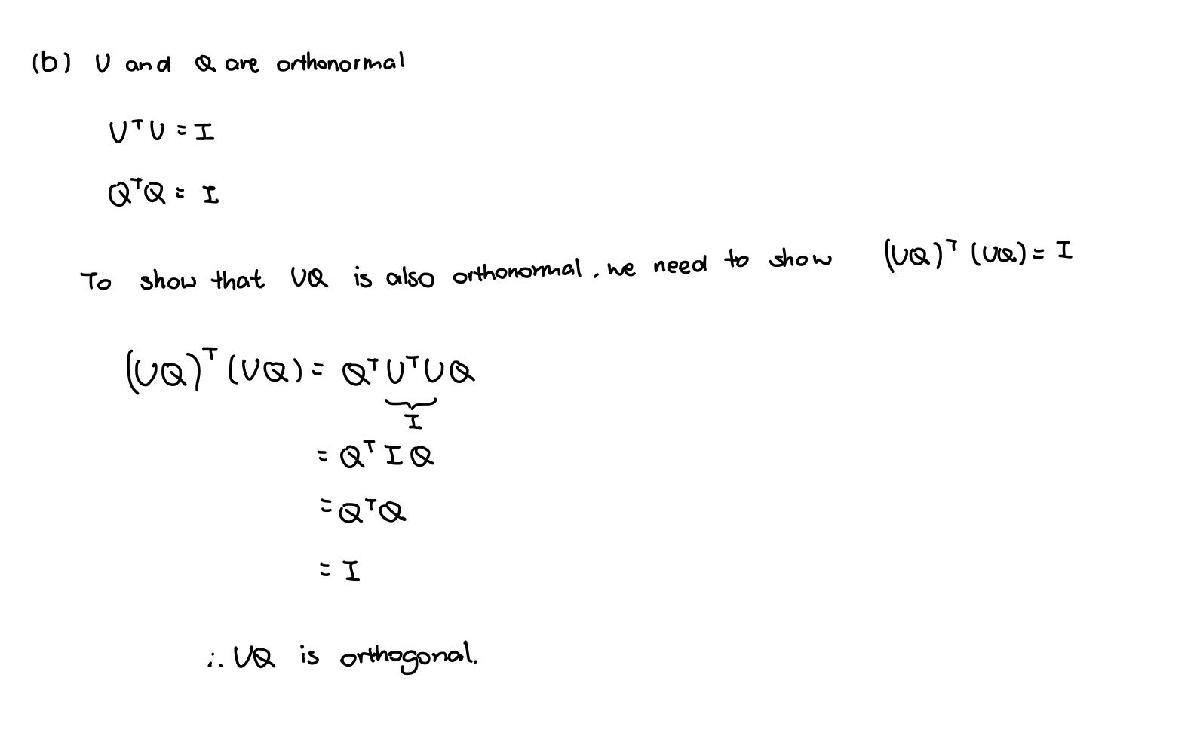

c) If A is an invertible matrix and Q is an orthonormal matrix, show that $\kappa \left(\textrm{QA}\right)=\kappa \left(A\right)\ldotp$

*% ANSWER*

## 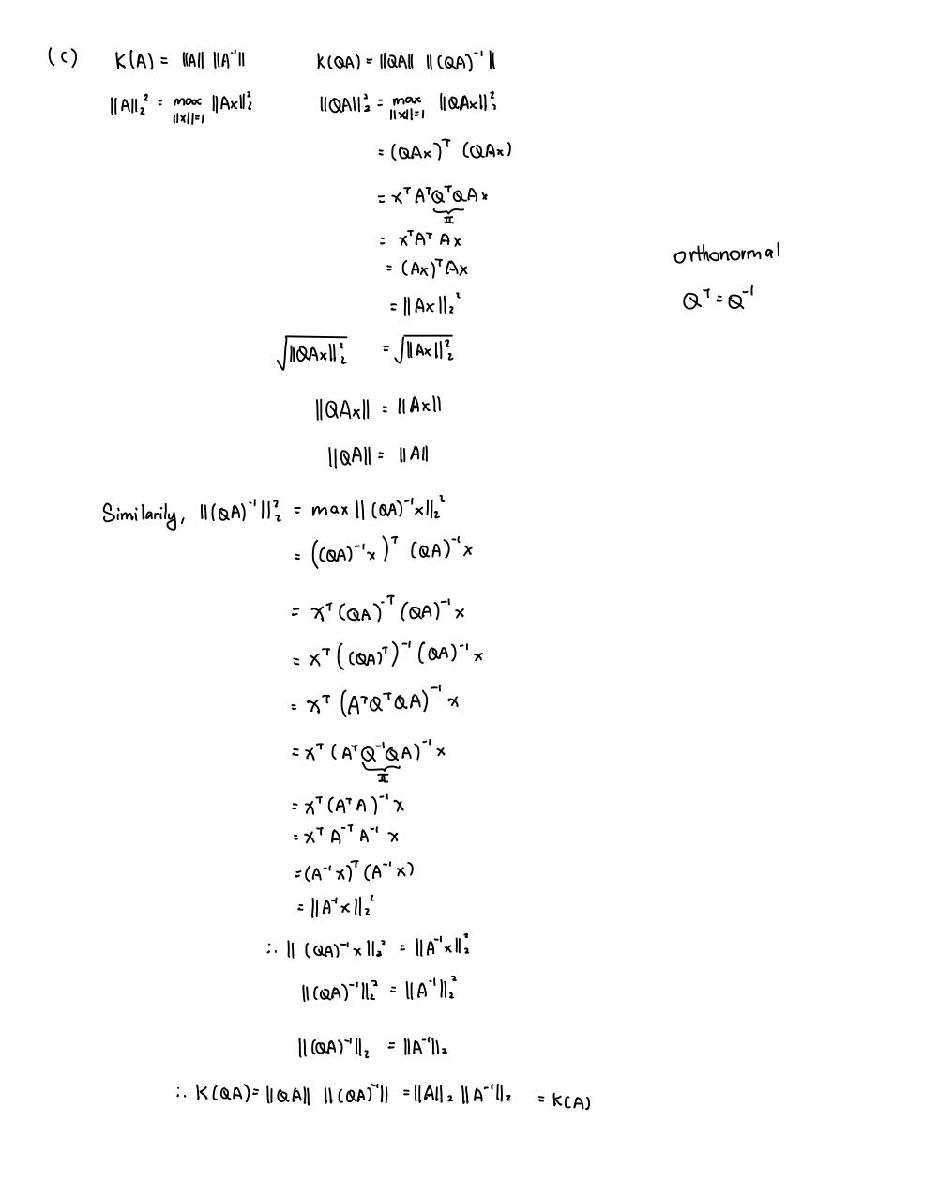

## Question 3:  QR Decomposition **(10 marks)**

 In this question we will develop the different algorithms to implment QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qgs,Rgs] = gschmidt(A);
   
   %use the norm to check 
   normGS = norm(A-Qgs*Rgs,'fro') ;
   
   disp(normGS);

   5.5390e-16



        Comment: The Gram-Schmidt based QR decomposition has potential unstable numerical issues, particularly for large matrices and matrices that have nearly linearly dependent columns, due to the rounding errors present in the vectors subtraction from projections. It is not recommended to use the GS based because it is not convenient for matrices close to singular or ill-conditioned.

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qmgs,Rmgs] = mgschmidt(A);
   
   normMGS = norm(A-Qmgs*Rmgs,'fro');

   disp(normMGS);

   4.1168e-16



        Comment: The modified Gram-Schmidt based QR decomposition is a better choice compared to the one of GS based since it is much more stable because it avoids the errors accumulation through changing the order of vector computation in each iteration of projections. Hence modified GS approach provides much better numerical stability.

## **Question 4:  Polynomial Fitting using Least Squares Estimation  (10 marks)**

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{Y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


The system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ can then be solved to compute the coefficients in vector $\mathit{\mathbf{a}}\ldotp$

a) Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the polynomial matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function *PolynomialMatrix* in the appendix.

% test your code here by inputing X= [ 1 2 3] for degree 3. 

% You can manually verify if this matrix is implemented correctly.

X= [ 1; 2; 3];
Mtest = PolynomialMatrix(X,3)

Mtest =      1     1     1     1
     1     2     4     8
     1     3     9    27


b) The least squares method can be used to solve the overdetermined linear system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ to obtain the polynomial coefficients. This can be done by directly solving the Normal equations (using cholesky decomposition for example) or by using QR decomposition. In the code below, use the **MATALB's QR decomposition function** to find the polynomial coefficients if we assume a polynomial model of order 1. 

% Load the Input Data from the provided .mat file 

load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 2/Polynomial_Fitting_Data.mat');
    
x = x_given;
y = y_given;
deg = 1;

% get Polynomial Matrix 
M = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(M,0);
   
   % Find the polynomial coefficients using Q & R matrices obtained obove.
   % For forward and backward substitution functions use the forward
   % substitution and the backward substitution you wrote in Assignment 1
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
  b = Q'*y;
  Ar = backward_sub(R,b);
   

Now that you have obtained the coefficients for the first order polynomial model, $p\left(x\right)=a_0 +a_1 x$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Run the code below and explain the results obtained in the figure. Is this order sufficient?**

   xtest = x;
   
   px = zeros(length(xtest),1);
   powers = 0:deg;
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
   end
   %plots
    figure;
   hold on;
   plot(x,y,'ro');
    plot(x,y,'gd');
   plot(xtest,px,'b-.','Linewidth',2);
   xlabel('x');
   ylabel('y');
   legend(' Given Data','Used Data','Obtained Model');
   grid on;
   title({'Question 4b';'The obtained  model using 1^{st} degree Polynomial'});

        Comment: The graph above displays a curving trend with no outliers. the obtained model line does not well-fit to data points trend.  As this graph illustrates, it does not have a straight line for the data points but instead it has a varying trend. Therefore, this order is not sufficient since the obtained model line does not fit well to the data points.

c) In this part we will use a higher order model (a polynomial of order 6), but only a limited amount of input data points to generate this model (we will use only** 15 data points)**. Use QR decomposition function to find the polynomial coefficients for the **6th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 2/Polynomial_Fitting_Data.mat');

deg = 6; %polynomial degree
x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp,0);
   
   disp(R);

   1.0e+04 *

   -0.0004   -0.0013   -0.0057   -0.0292   -0.1585   -0.8948   -5.1946
         0    0.0008    0.0051    0.0310    0.1856    1.1181    6.7959
         0         0    0.0014    0.0138    0.1054    0.7350    4.9361
         0         0         0   -0.0025   -0.0322   -0.2966   -2.3716
         0         0         0         0   -0.0042   -0.0687   -0.7425
         0         0         0         0         0    0.0070    0.1371
         0         0         0         0         0         0    0.0113



   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
   b = Q' * y;
   Ar = backward_sub(R,b);
 

We can test this model by evaluating $p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_6 x^6$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5c, and explain the cause of what you see.**


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' All of the Data','Data used','Obtained Model')
   title({'Question 4c';'The obtained  model using 6^{th} degree Polynomial'})
   grid on

        Comment: The plot above demonstrates a well-fit obtained model line to the data points. Hence it is a good model. However, high degree polynomials could lead to overfitting as we see in this plot, which is not advantageous for generalizing new data points since it fits the data points too close. The reason why I see this is because of high degree polynomials as I mentioned before, particularly, for a small subset of data points like this situation since it lacks generalization to other datasets.

d ) In this part we will use a polynomial of order **14,**  again this will be used with limited amount of data (we will use only** 15 data points, same as part c**). Use QR decomposition function to find the polynomial coefficients for the **14th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 2/Polynomial_Fitting_Data.mat');

deg =14

deg = 14

x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
 b = Q' * y;
 Ar = backward_sub(R,b);
 

We can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5d, and explain the cause of what you see.**


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure('Name','Question 4d','NumberTitle','off')
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   ylim([-70 70])
   legend(' All of the Data','Data used','Obtained Model')
 title({'Question 4d';'The obtained  model using 14^{th} degree Polynomial'})
   grid on

        Comment: This is not a good model. The plot above displays irregular trends at the beginning and at the end, close to 0 and 6.5 respectively. The reason why this phenomenon happens is that the 14th degree polynomial tries to covers all the data points which causes it overfitts the data. In other words, it highlights the fluctuations among the data sets instead of just underlying the trend. Hence it is a bad model.

## Appendix 

## * Implement the Cholesky Decompositon fucntion here.*

function U =  CholeskyDecompositon(M)
if(size(M,1) ~= size(M,2))
    disp('Matrix M must be square!');
    
end
U = zeros(size(M));
% Write your code here.
[n,n] = size(U);

    for i = 1:n
        for j = 1+i:n
            if i==j 
                U(i,j) = sqrt(M(i,i) - U(1:i-1, i)' * U(1:i-1,i) );

            elseif j>i
                U(i,j) = (M(i,j) - U(1:i-1, i)' * U(1:i-1,j) ) / U(i,i);
            
            else 
                U(i,j) = 0;
            end
        end
    end
end

## *Implement Least Square Solver for Cholesky here*

function x = LeastSquareSolver_Cholesky(A,b)
% get M = A^T A
M = A'*A;

% write your code here
% Step 1. Call the choesky function written in part (a) to get Lower triangular matrix,L
   % M = L L^T
   U = CholeskyDecompositon(M);

% Step 2. Use the forward substitution function named  ForwardSubs() you  wrote in Assignment 1
    y = forward_sub(U', A' * b);
          
% Step 3. Use the backward substitution function BackwardSubs()  you  wrote in Assignment 1
          
    x = backward_sub(U,y);

end


% forward and backward substitution functions from Assignment 1
function y = forward_sub(L,b)
% y is the vector
% L is the lower triangular matrix
    n = length(b);
    y = zeros(n,1);
    for i = 1:n
        y(i) = ( b(i) - L(i, 1: i-1) * y(1:i-1) ) / L(i,i);
    end
end 

function x = backward_sub(R, b)
    % X is the vector
    % U is the upper triangular matrix
    n = length(b);
    x = zeros(n, 1); % Preallocate space for the solution vector x

    for i = n:-1:1
        x(i) = (b(i) - R(i, i+1:n) * x(i+1:n)) / R(i, i);
    end
end

## *Implement Polynomial Matrix here *

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
    M = ones(length(x), n+1);

    for i = 1:n
        M(:, i+1) = x.^i;
    end
end


## *Implement QR Methods here*

- *Classical GramSchmidt *

function [Q,R] = gschmidt(A)
   % A is the input matrix- 
   % A could be a overdetermined matrix or a sqaure matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 
   
   % Write your code here.
   [x,y] = size(A);
   
   Q = zeros(x,y);
   R = zeros(y,y);

   for j = 1:y
       z = A(:,j);
       for i = 1:j-1
           R(i,j) = Q(:, i)' * A(:,j);
           z = z - R(i,j) * Q(:,i);
       end

       R(j,j) = norm(z);
       Q(:,j) = z/ R(j,j);
   end
end

- *Modified Gram-Schimdt*


function [Q,R] = mgschmidt(A)
 % A is the input matrix- 
   % A could be a overdetermined matrix or a sqaure matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 
   
   % Write your code here.
   [x,y] = size(A);

   Q = zeros(x,y);
   R = zeros(y,y);

   for i = 1:y
       R(i,i) = norm(A(:,i));
       Q(:,i) = A(:,i) / R(i,i);
       for j = i+1:y
           R(i,j) = Q(:,i)' * A(:,j);
           A(:,j) = A(:,j) - R(i,j) * Q(:, i);
       end
   end
end
   

## *Function to generate Hilbert Matrix is provided here*

function A = Hilbert_matrix(size)

A = zeros(size,size);

for i=1:size
    for j=1:size
        A(i,j) = 1/(i+j-1);
    end 
end 
end